Copyright © 2021  Shababuddin Khan || sk@pcampus.edu.np

*Department of Electrical Engineering, *[Pulchowk Campus](https://pcampus.edu.np/)*, Tribhuwan University, Nepal*

A Series of  Module has been designed and developed by author mentioned above with full copyright for a course of **Control System** to demonstrante the concept of control system and its implementation in real life to second year Aerospace engineering students at Tribhuwan University.

# ***MODULE 2: Modelling of System By Script***

The first step in the control design process is to develop appropriate mathematical models of the system to be controlled. Physical laws or experimental data can be used to create these models. We can use tranfer function to model the system.

# **2.1 Transfer Function**

Mathematically it is defined as the ratio of Laplace transform of output (response function) and Laplace transform of input (driving function) by assuming all the initial conditions are zero.


$$\mathrm{TF}=L\frac{c\left(t\right)}{r\left(t\right)}|_{\mathrm{all}\;\mathrm{initail}\;\mathrm{condition}\;\mathrm{zero}}$$



$$\mathrm{TF}=\frac{C\left(s\right)}{R\left(s\right)}$$


## 2.1.1 Input Parameters of System

% Directly define the parameter of the system
R=1;
L=2;
disp(R)

     1



L

L = 2

## 2.1.2 Transfer Function in MATLAB 

% By Defining s as a variable
s=tf('s');           
%Create tf objects representing continuous-time or discrete-time transfer functions in polynomial form.
sys1=10/(s^2+5*s+4);
sys1


sys1 =
 
       10
  -------------
  s^2 + 5 s + 4
 
Continuous-time transfer function.



% By using tf directly
num=[0,2,5];
den=[1,4,3];
sys2=tf(num,den);
sys2


sys2 =
 
     2 s + 5
  -------------
  s^2 + 4 s + 3
 
Continuous-time transfer function.



% Defining Directly
sys3=tf([2,4],[1,4,5])


sys3 =
 
     2 s + 4
  -------------
  s^2 + 4 s + 5
 
Continuous-time transfer function.



% By Zero, Poles and Gain
% Use of zpk() Function
z=[2,1];
p=[1,3,5];
k=10;
sys4=zpk(z,p,k)


sys4 =
 
   10 (s-2) (s-1)
  -----------------
  (s-1) (s-3) (s-5)
 
Continuous-time zero/pole/gain model.



## 2.1.3 Poles and Zeros of Transfer Function

% use pole() and zero() function
p=pole(sys2);
z=zero(sys2);
% We can use zpkdata() to get zero, poles and gain
[Z,P,k]=zpkdata(sys4,'v')

Z =      2
     1


P =      1
     3
     5


k = 10

[~,~,Gain]=zpkdata(sys4,'v') % To avoid their calculation ~ used

Gain = 10

## 2.1.4 Plot of P-Z

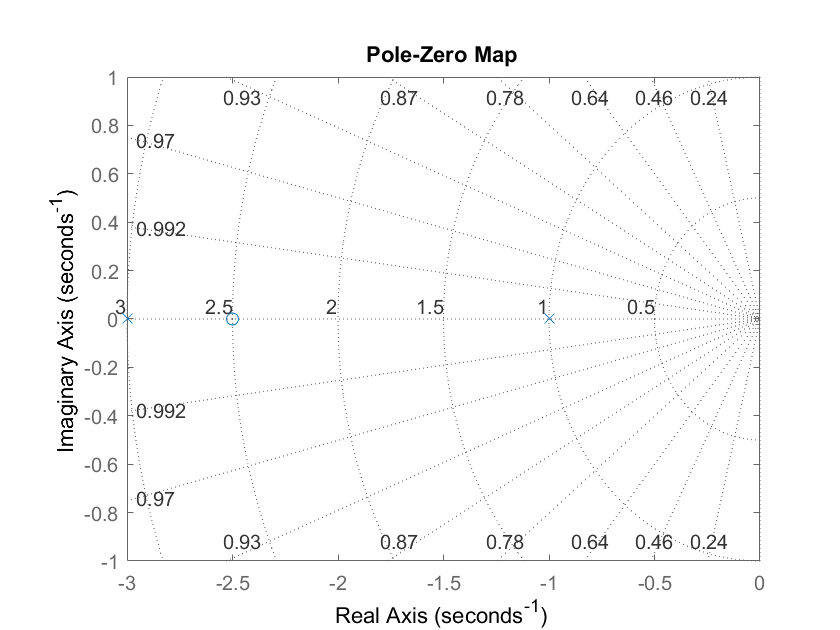

% pzplot() is used to plot p-z graph
%Plot for single Transfer Function
pzplot(sys2)
grid on    % Displays lines of constant damping ratio (zeta) and lines of constant natural frequency (wn)

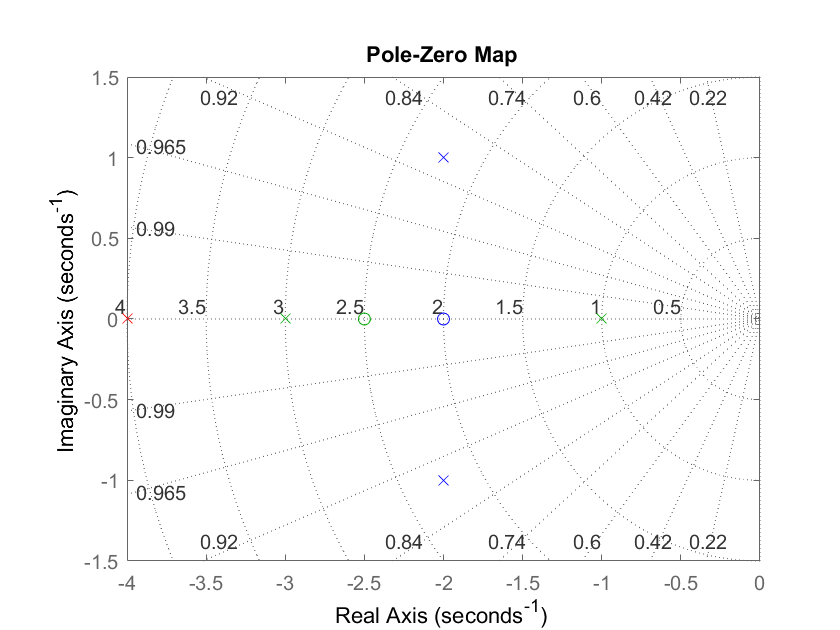

%Plot multiple system in one P-Z Plane
pzplot(sys1,'r',sys2,'g',sys3,'b')
grid on

# 2.2 Mathematical Modelling of Mechanical System

## 2.2.1 Simple Spring System

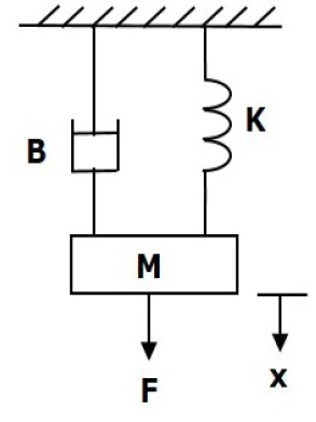


$$\mathrm{𝐹}=M\;\frac{d^2 x}{{\mathrm{dt}}^2 }+B\;\frac{\mathrm{dx}}{\mathrm{dt}}+\mathrm{Kx}$$



$$\frac{X\left(s\right)}{F\left(s\right)}=\frac{1}{{\mathrm{Ms}}^2 +\mathrm{Bs}+K}$$


% Initialization with Parameters of the system
M= 2;    % Mass in Kg
B= 0.3;  %Damiping COnstant in Ns/m
K=3;     % Spring Constant in N/m

% Model the Model using Transfer Function
s=tf('s');
M_sys=1/(M*s^2+B*s+K)


M_sys =
 
          1
  -----------------
  2 s^2 + 0.3 s + 3
 
Continuous-time transfer function.



## 2.2.2 Cruise System

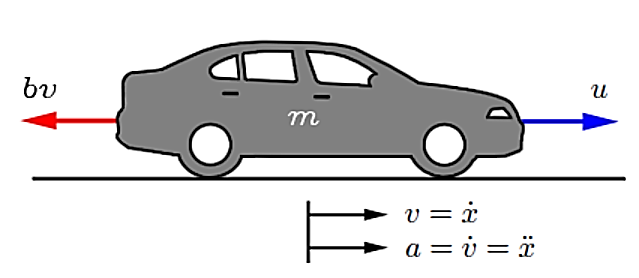

Fig: Cruise System[2]

For Force u acting on the cruise,


$$u=m\frac{d^{2\;} x}{{\mathrm{dt}}^2 }+b\frac{\mathrm{dx}}{\mathrm{dt}}$$


To maintain constant Speed, the cruise will be modelled as,


$$u=m\frac{\mathrm{dv}}{\mathrm{dt}}+\mathrm{bv}$$


So, Transfer function is,


$$\frac{V\left(s\right)}{U\left(s\right)}=\frac{1}{m\;s+b}$$


% Initializing the Parameters of the system
m=2000; %Vechile Mass in Kg
b=50;   % Damping Coefficiennt in Ns/m

% Mathematical Modelling Using Transfer Function
n=1;
d=[m,b];
cruise_tf=tf(n,d)


cruise_tf =
 
       1
  -----------
  2000 s + 50
 
Continuous-time transfer function.



# 2.3 Mathematical Modelling of Electrical System

## 2.3.1 Simple RL Circuit

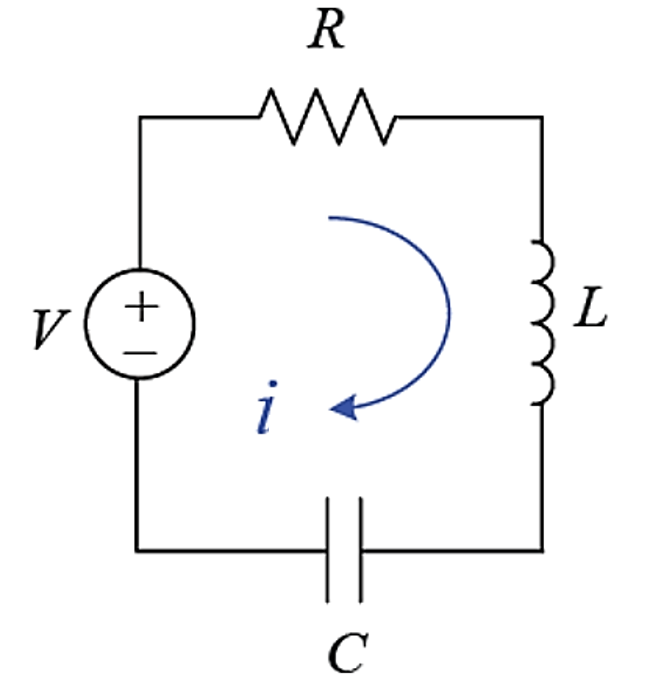

Fig: RLC Circuit [2]


$$V=\mathrm{RI}\left(s\right)+\mathrm{LsI}\left(s\right)+\frac{I\left(s\right)}{\mathrm{Cs}}$$



$$\frac{I\left(s\right)}{R\left(s\right)}=\frac{s\;C}{s^2 \;\mathrm{LC}+s\;\mathrm{RC}+1}$$


% Define the Parameters
R=1;       % Resistance in Ohm
L=0.04;    % Inductance in Henry
C=2*10^-6;   % Capacitance in Farad
%C=2e-6
s=tf('s');
RLC_TF1=(s*C)/(s^2*L*C+s*R*C+1)


RLC_TF1 =
 
          2e-06 s
  -----------------------
  8e-08 s^2 + 2e-06 s + 1
 
Continuous-time transfer function.




%By tf but it require a careful representation of numerator
n=[C 0];
d=[L*C,R*C,1];
RLC_TF2=tf(n,d)


RLC_TF2 =
 
          2e-06 s
  -----------------------
  8e-08 s^2 + 2e-06 s + 1
 
Continuous-time transfer function.



## 2.3.2 Armature Controlled DC Motor [Position Control]

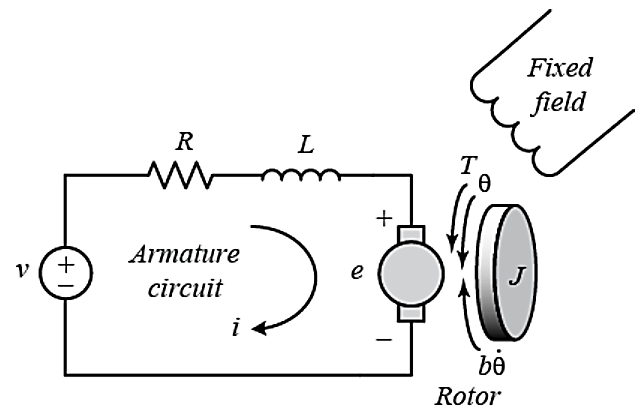

Fig: Equivalent Circuit of DC Motor [2]

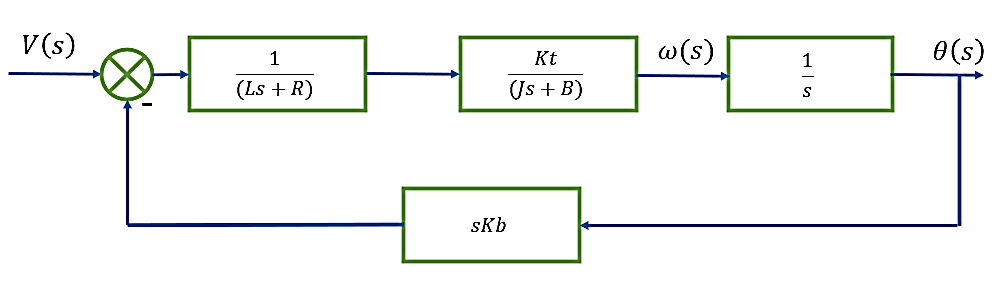

*Fig: Block-Diagram Model of Armature Controlled DC Motor[Position]*

$\frac{\theta \left(s\right)}{V\left(s\right)}=\frac{K}{s\left\lbrace \left(\mathrm{Js}+b\right)\left(\mathrm{Ls}+R\right)+K^2 \right\rbrace }$ rad/Volt

We will assume the following values for the physical parameters. These values were derived by experiment from an actual motor in **Carnegie Mellon's undergraduate controls lab.[2]**

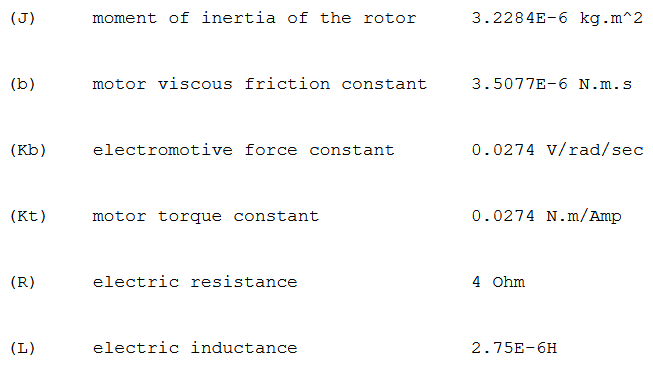

J = 3.2284E-6;
b = 3.5077E-6;
K = 0.0274;
R = 4;
L = 2.75E-6;
s = tf('s');
Position_motor = K/(s*((J*s+b)*(L*s+R)+K^2))

$$a = \left(\begin{array}{cc} 1 & -\frac{s}{\left(s+2\right)\,\left(s+3\right)} \end{array}\right)$$

## 2.3.3 Field Controlled DC Motor [Speed Control]

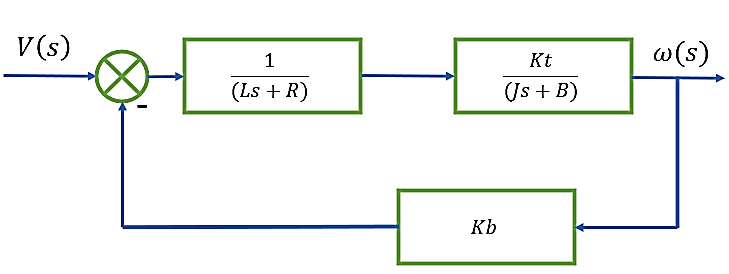

*Fig: Block-Diagram Model of Armature Controlled DC Motor[Speed]*

$\frac{\omega \left(s\right)}{V\left(s\right)}=\frac{K}{\left(\textrm{Js}+b\right)\left(\textrm{Ls}+R\right)+K^2 }$ rad/sec/Volt

% Parameter Initialization
J = 0.01;
b = 0.1;
K = 0.01;
R = 1;
L = 0.5;
% Defining The Transfer Function
s = tf('s');
Speed_motor = K/((J*s+b)*(L*s+R)+K^2)


P_motor =
 
             0.01
  ---------------------------
  0.005 s^2 + 0.06 s + 0.1001
 
Continuous-time transfer function.



## 2.3.4 Op-Amp Circuit

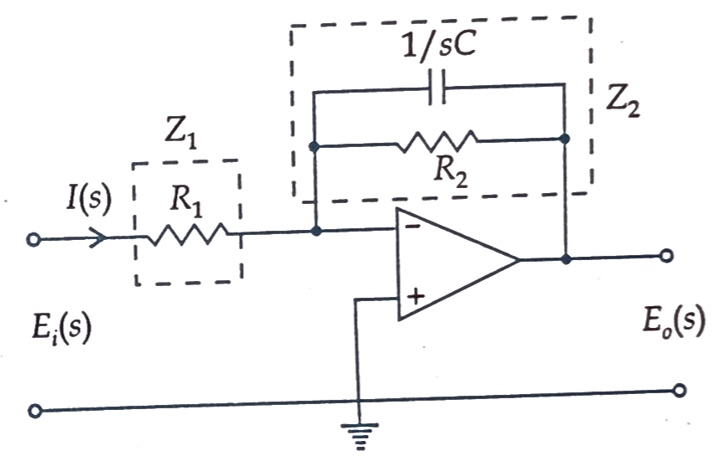


$$\frac{E_{o\;} \left(s\right)}{E_i \left(s\right)}=\left(-\frac{R_2 }{R_1 \left(1+{\mathrm{sCR}}_2 \right)}\right)$$


% Inintialization of Parameters
R1=4;
R2=3;
C=3e-6;
% Defining The Transfer Function
s=tf('s');
Opamp_tf=(-R2*s)/(R1*(1+s*C*R2))


Opamp_tf =
 
      -3 s
  -------------
  3.6e-05 s + 4
 
Continuous-time transfer function.



# References

- Mathworks.inc

- [https://ctms.engin.umich.edu/CTMS/index.php?aux=Home](https://ctms.engin.umich.edu/CTMS/index.php?aux=Home)

- Bakshi, Uday A., and Varsha U. Bakshi. *Control system engineering*. Technical Publications, 2020.

- Nise, Norman S. "Control system engineering, John Wiley & Sons." *Inc, New York*(2011).